# Implementacja algorytmu radix-2

N = 1024;
xCpp = randn(N,2); 
xMat = xCpp(:,1) + xCpp(:,2).*1i;
save('x.mat','xMat');
save('xcpp.dat','xCpp','-ascii');


Data test:

xCppTest = load('xcpp.dat');
xMatTest = load('x.mat').xMat;

XCppTest = fft(xCppTest(:,1)+xCppTest(:,2).*1i);
XMatTest = fft(xMatTest);

diffrece = sum(XMatTest-XCppTest);

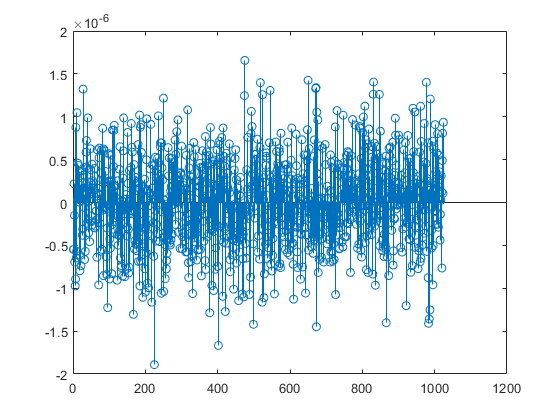


clf
figure
stem(XCppTest - real(XMatTest))